# 802.11 OFDM Beacon Frame Generation

This example shows how to generate packets containing medium access control (MAC) beacon frames suitable for baseband simulation or over-the-air transmission using a software-defined radio (SDR) platform.

## Introduction

In this example, you create an IEEE® 802.11™ beacon frame as described in section 9.3.3.3 of [ 1 ]. You can view the beacon packet transmitted using SDR by using A Wi-Fi device, as shown in this figure.

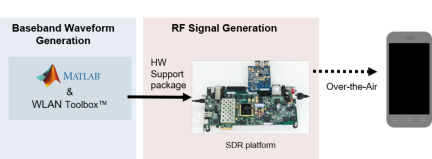

A beacon frame is a type of management frame that identifies a basic service set (BSS) formed by some 802.11 devices. The beacon frame consists of a MAC header, a beacon frame body and a valid frame check sequence (FCS). The beacon frame body contains information fields that allow stations to associate with the network.

You can store the generated waveform in a baseband file format. 

You can also transmit the generated waveform over the air. Upconvert the beacon packet for RF transmission using Xilinx® Zynq-Based Radio SDR hardware. The radio hardware can transmit the waveform over the air.

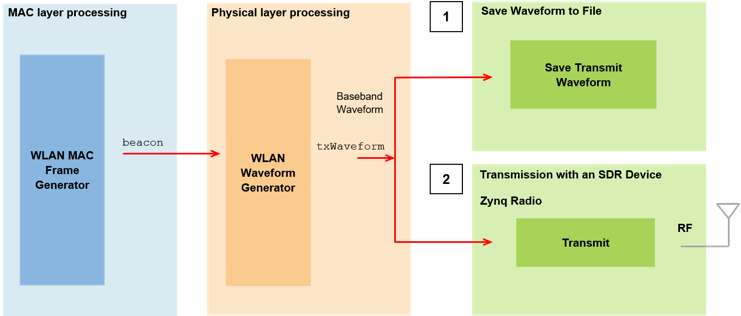

Transmitting the beacon over the air requires the Xilinx Zynq-based radio support package, which you can install with the [Add-On Explorer](matlab:supportPackageInstaller). For more information about SDR platforms, see [Hardware Support: Communications Toolbox](https://www.mathworks.com/hardware-support.html?fq=product:CM).

## Example Setup

The beacon packet can be written to a baseband file and transmitted using an SDR platform. To transmit the beacon using the SDR platform set `useSDR` to true. To write to a baseband file set `saveToFile` to true.

useSDR = true;
saveToFile = true;

## Create IEEE 802.11 Beacon Frame

A station (STA) periodically transmits beacon packets as specified by the target beacon transmission time (TBTT) in the Beacon Interval field. The beacon interval represents the number of time units (TUs) between TBTTs, where 1 TU represents 1024 microseconds. A beacon interval of 100 TUs results in a 102.4 millisecond time interval between successive beacons. You can generate a beacon frame by using the [`wlanMACFrame`](docid:wlan_ref#mw_9f2e549d-99ee-49ae-b9c3-3a78e29a6c1a) function with medium access control (MAC) frame configuration object [`wlanMACFrameConfig`](docid:wlan_ref#mw_a004c76e-748e-42b5-84b2-360a063ea1f9) and MAC frame-body configuration object [`wlanMACManagementConfig`](docid:wlan_ref#mw_083f69be-10d7-4935-9f2e-e487f2aa75a9).

Specify the network service set identifier (SSID), beacon interval, operating band, and channel number.

ssid = "TEST_BEACON";
beaconInterval = 100;
band = 2.4;
chNum = 6;

Create a MAC frame-body configuration object, setting the SSID and Beacon Interval field value.

frameBodyConfig = wlanMACManagementConfig( ...
    BeaconInterval=beaconInterval, ...
    SSID=ssid);

Add the DS Parameter information element (IE) to the frame body by using the [addIE](docid:wlan_ref#mw_95e395de-1600-444a-8ddd-e969caa81694) object function.

dsElementID = 3;
dsInformation = dec2hex(chNum,2);
frameBodyConfig = frameBodyConfig.addIE(dsElementID,dsInformation);

Create beacon frame configuration object.

beaconFrameConfig = wlanMACFrameConfig(FrameType="Beacon", ...
    ManagementConfig=frameBodyConfig);

Generate beacon frame bits.

[mpduBits,mpduLength] = wlanMACFrame(beaconFrameConfig,OutputFormat="bits");

Calculate center frequency for the specified operating band and channel number.

fc = wlanChannelFrequency(chNum,band);

## Create IEEE 802.11 Beacon Packet

Configure a non-HT beacon packet with the relevant PSDU length, specifying a channel bandwidth of 20 MHz, one transmit antenna, and BPSK modulation with a coding rate of 1/2 (corresponding to MC

S index 0) by using the [`wlanNonHTConfig`](docid:wlan_ref#buw6f2v) object.

cfgNonHT = wlanNonHTConfig(PSDULength=mpduLength);

Generate an oversampled beacon packet by using the [wlanWaveformGenerator](docid:wlan_ref#buwv1f3) function, specifying an idle time.

osf = 1;
tbtt = beaconInterval*1024e-6;
txWaveform = wlanWaveformGenerator(mpduBits,cfgNonHT,... 
    OversamplingFactor=osf,Idletime=tbtt);

Get the waveform sample rate.

Rs = wlanSampleRate(cfgNonHT,OversamplingFactor=osf);

## Save Waveform to File

Save the waveform in a baseband file using the [comm.BasebandFileWriter](docid:comm_ref#bvby020-1) object.

if saveToFile
    bbw = comm.BasebandFileWriter("nonHTBeaconPacket.bb",Rs,fc); %#ok<UNRCH>
    bbw(txWaveform);
    release(bbw);
end

## Visualize Frequency Spectrum

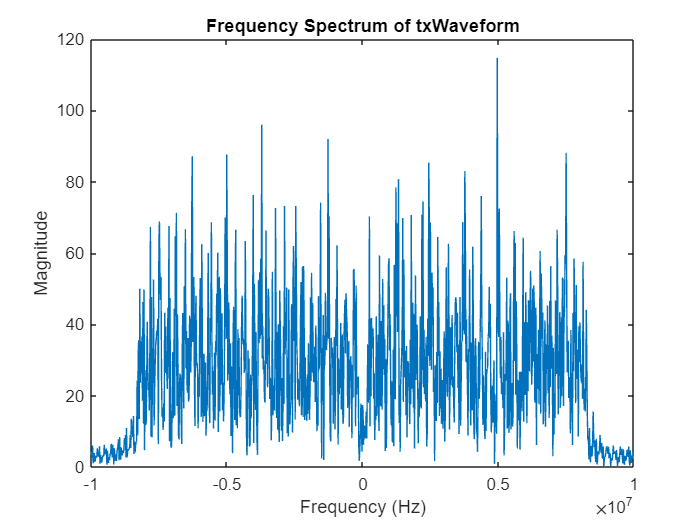

% Compute and plot the frequency spectrum
nfft = 1024;
f = (-nfft/2:nfft/2-1)*(Rs/nfft);  % Frequency vector
spectrum = fftshift(fft(txWaveform, nfft));  % Compute FFT

figure;
plot(f, abs(spectrum));
title('Frequency Spectrum of txWaveform');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

in time

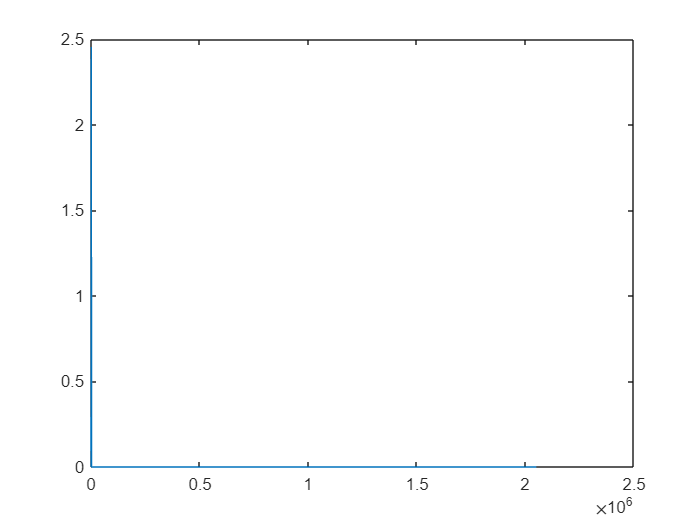

plot(abs(txWaveform))

## Simulated Channel Estimation

Adding white noise to beacon signal.

txWaveform_ = awgn(txWaveform * (-0.1 + 0.5i), 60);

Computing the indices for the L-LTF in a nonHT WLAN config and extracting it from the signal and then demodulating it.

idxLLTF = wlanFieldIndices(cfgNonHT, 'L-LTF');
demodSig = wlanLLTFDemodulate(txWaveform_(idxLLTF(1):idxLLTF(2), :), cfgNonHT);

Getting the channel estimation based on the demodulated signal.

est = wlanLLTFChannelEstimate(demodSig, cfgNonHT);

Plotting it. 

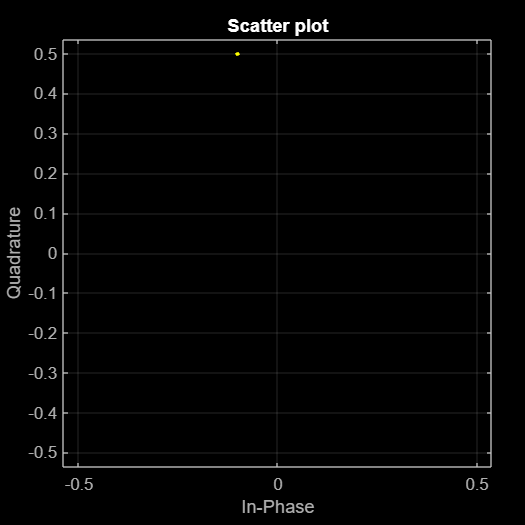

scatterplot(est);
grid;

## Transmission with an SDR Device

In this section, you transmit the beacon packet over the air using an SDR device.

if useSDR
    tx = comm.SDRuTransmitter(...
    'Platform', 'B210', ...
    'SerialNum', '344C57A', ...
    'CenterFrequency', fc, ...
    'MasterClockRate', Rs, ...
    'Gain', 70, 'InterpolationFactor', 2); % Adjust gain as needed
    
    txWaveform_ = txWaveform_(:);

    txWaveform_ = txWaveform_./max(abs(txWaveform_));

    % Stream the waveform
    for k = 1:1
        tx(txWaveform_);
    end

    % Release the transmitter when done
    release(tx);
end

Win32; Microsoft Visual C++ version 14.2; Boost_107800; UHD_4.2.0.0-vendor

---------- see libuhd version information above this line ----------


To impair the signal or reduce transmission quality of the waveform, you can adjust the transmitter gain `tx.Gain`. This parameter, expressed in dB, drives the power amplifier in the radio. You can use these suggested values, or select different values appropriate for your antenna configuration.

- For increased gain, set the `tx.Gain` parameter to `0`.

- For default gain, set the `tx.Gain` parameter to `-10`.

- For reduced gain, set the `tx.Gain` parameter to `-20`.

Transfer the baseband waveform to the SDR platform by using the `transmitRepeat` function, and then store the signal samples in hardware memory. The example then repeatedly transmits this waveform over-the-air until the release method of the transmit object is called. Messages are displayed in the command window to confirm that transmission has started successfully.

%if useSDR
    % Set transmit gain
 %   tx.Gain = 0; %#ok<UNRCH>
    % Transmit over the air
 %   transmitRepeat(tx,txWaveform);
%end

## Conclusion and Further Exploration

This example shows how to generate a beacon packet for the IEEE 802.11 standard and view the beacon packet transmitted using SDR hardware by using a Wi-Fi device. You can use the stored baseband beacon packet to recover the transmitted information using the [OFDM Beacon Receiver Using Software-Defined Radio](docid:wlan_ug#mw_b7f3c697-70a6-412c-b0fb-c450f0161f8d) example.

## Related Examples

- [OFDM Beacon Receiver Using Software-Defined Radio](docid:wlan_ug#mw_b7f3c697-70a6-412c-b0fb-c450f0161f8d)

- [Recover and Analyze Packets in 802.11 Waveform](docid:wlan_ug#example-AnalyzePacketsExample)

- [802.11 MAC Frame Generation](docid:wlan_ug#example-MACFrameGenerationExample)

## References

- IEEE Std 802.11™-2020 IEEE(Revision of IEEE Std 802.11-2016). “Part 11: Wireless LAN Medium Access Control (MAC) and Physical Layer (PHY) Specifications.” IEEE Standard for Information technology — Telecommunications and information exchange between systems. Local and metropolitan area networks — Specific requirements.

*Copyright 2016-2022 The MathWorks, Inc.*